close all;
clear all;

%[success, variant_out, model_out, exitInfo]= sbiosteadystate(ans);
m1 = createEndometriosisModel3();

nva = struct with fields:
        ssIGF1: 15.6883
       ssIGFBP: 80
      ssIGFBPc: 120
       ssPAPPA: 0.2000
      ssPAPPA2: 0.0013
        rpIGF1: 128.7343
        raIGF1: 9.2500e-04
        trIGF1: 0.1670
       trIGFBP: 16
      trIGFBPc: 16
       trPAPPA: 100
      trPAPPA2: 100
         Kcat2: 1116
           Km2: 410
          Kcat: 3204
            Km: 1630
        FupmAB: 1
         ssARG: 100000
        ssARGi: 80000
          ssNO: 46
         trARG: 2
        trARGi: 1
          trNO: 5.5000e-07
         rpARG: 41.6000
         raARG: 9.2500e-04
        FupARG: 1
        ssPGE2: 1.1348
         ssEP3: 1.6670
      kpainEP3: 0.2821
    kelpainEP3: 1
      kinChOFF: 0.8000
        trPGE2: 0.1500
         trEP3: 12
           kon: 1
          koff: 5.8000
    exportFlag: 0
     kdegIGFBP: 0.0433
    kdegIGFBPc: 0.0433
     kdegPAPPA: 0.0069
    kdegPAPPA2: 0.0069
      kdegIGF1: 4.1506
       kinChON: 0.4000
     ksynIGFBP: 33.4447
    ksynIGFBPc: 5.5321
      ksynIGF1: 34.

r1 = 29.9789

r2 = 0.3335

ans =    SimBiology Parameter Array

   Index:    Name:       Value:      Units:
   1         kdegARGi    0.693147    1/hour



cs = getconfigset(m1);
cs.RuntimeOptions.StatesToLog = 'NchSig';

d = adddose(m1,'Test Dose');
d.AmountUnits = 'nanomole';
d.TargetName = 'IGF1';
d.TimeUnits = 'hour';
d.StartTime = 40;
%d.Amount = 100;
%d = getdose(m1,'Test Dose');
amountParam = addparameter(m1,'AmountParam','Units',d.AmountUnits);
d.Amount = 'AmountParam';
d.Active = 1;
doseSamples = SimBiology.Scenarios('AmountParam',linspace(10,100,30));

% Suppress informational warnings that are issued during simulation.
warning('off','SimBiology:SimFunction:DOSES_NOT_EMPTY');
f = createSimFunction(m1,doseSamples,'NchSig',d)

f = SimFunction

Parameters:

         Name          Value        Type            Units    
    _______________    _____    _____________    ____________

    {'AmountParam'}      1      {'parameter'}    {'nanomole'}

Observables: 

       Name          Type             Units      
    __________    ___________    ________________

    {'NchSig'}    {'species'}    {'nanomolarity'}

Dosed: 

    TargetName              TargetDimension                  Amount         AmountValue    AmountUnits 
    __________    ___________________________________    _______________    ___________    ____________

warning('on','SimBiology:SimFunction:DOSES_NOT_EMPTY');


doseTable = getTable(d);
sd = f(doseSamples,cs.StopTime,doseTable)

 
   SimBiology Simulation Data Array: 30-by-1
 
   ModelName:        PAPPA2model
   Logged Data:
     Species:        1
     Compartment:    0
     Parameter:      0
     Sensitivity:    0
     Observable:     0
 


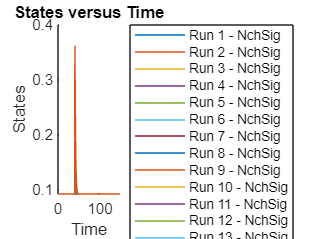


h = sbioplot(sd);

time = sd(1).Time;

warning('off','SimBiology:sbservices:SB_DIMANALYSISNOTDONE_MATLABFCN_UCON');
newSD = addobservable(sd,'stat1','max(NchSig) ','Units','nanomolarity')

 
   SimBiology Simulation Data Array: 30-by-1
 
   ModelName:        PAPPA2model
   Logged Data:
     Species:        1
     Compartment:    0
     Parameter:      0
     Sensitivity:    0
     Observable:     1
 


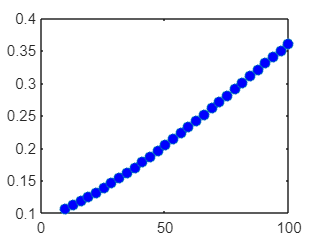

scalarObs = vertcat(newSD.ScalarObservables);
doseAmounts = generate(doseSamples);
figure
plot(doseAmounts.AmountParam,scalarObs.stat1,'o','MarkerFaceColor','b')